M=Model(false);%Create model without robot
in = zeros(1,4);%declaring in
in(1)=185;
in(2)=170;
in(3)=154;
in(4)=0;
out=M.robot.step2ik(in(1:3),in(4))%run the inverse kinimatics

out =    42.5805   -3.3240   38.5376  -35.2136


figure;%reset the plot before a new plot is made
result=M.plot_arm(out)%plot the result of running the forward kinimatics of the output of the inverse kinimatics

result =     0.7363   -0.0000   -0.6766  185.0000
    0.6766   -0.0000    0.7363  170.0000
   -0.0000   -1.0000    0.0000  154.0000
         0         0         0    1.0000


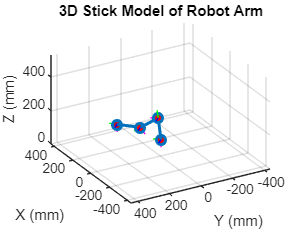

hold on;
plot3(in(1),in(2),in(3),'.','MarkerSize',10); %plot desired endpoint to compare with the resulting endpoint 

ee=result(1:3,4)' %get the end effector position out of the resulting transformation matrix

ee =   185.0000  170.0000  154.0000


error=ee-in(1:3) %compare the resulting end effector position with the desired end effector position

error = 1.0e-13 *

         0   -0.5684   -0.5684


errorNorm=norm(error) 

errorNorm = 8.0389e-14

Test new IK

NewOut=M.robot.step2ik2(in(1:3),in(4))

NewOut =    42.5805   -3.3240   38.5376  -35.2136


NewResult=M.fk(NewOut);
NewEE=NewResult'

NewEE =   185.0000
  170.0000
  154.0000


NewError=NewEE'-in(1:3)

NewError = 1.0e-09 *

   -0.4095   -0.3763    0.0713


NewErrorNorm=norm(NewError)

NewErrorNorm = 5.6069e-10

Time test

tic;
out=M.robot.step2ik(in(1:3),in(4));
oldTime=toc;
tic;
NewOut=M.robot.step2ik2(in(1:3),in(4));
newTIme=toc;
disp(oldTime)
disp(newTIme)

FK test

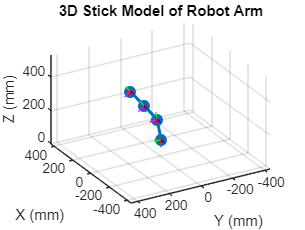

result =     0.0548    0.0677   -0.9962   16.2098
    0.6269    0.7742    0.0872  185.2792
    0.7771   -0.6293    0.0000  424.3628
         0         0         0    1.0000


M=Model(false);%Create model without robot
in = zeros(1,4);%declaring in
in(1)=85;
in(2)=0;
in(3)=-51;
in(4)=0;
figure;
view(3)
result=M.plot_arm(in)%plot the result of running the forward kinimatics of the output of the inverse kinimatics